# .

# +HW6 Programm Assignment

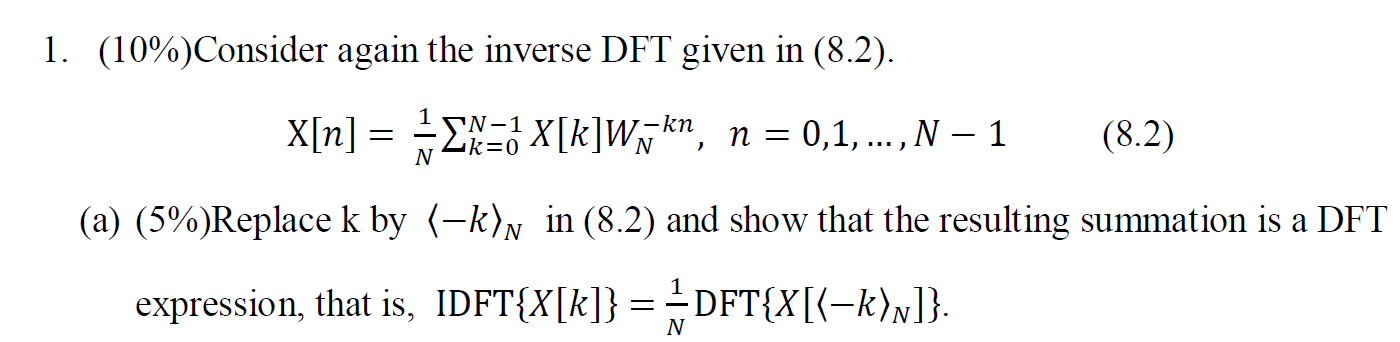

### 
$$\textrm{IDFT}\left\lbrace X\left\lbrack k\right\rbrack \right\rbrace =X\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack k\right\rbrack {W_N }^{-\textrm{kn}} =\frac{1}{N}\sum_{k=N}^1 X\left\lbrack {<-k>}_N \right\rbrack {W_N }^{-\left(N-k\right)n} =\frac{1}{N}\sum_{k=N}^1 X\left\lbrack {<-k>}_N \right\rbrack {W_N }^{\textrm{kn}} =\frac{1}{N}\sum_{k=1}^N X\left\lbrack {<-k>}_N \right\rbrack {W_N }^{\textrm{kn}} =\frac{1}{N}\textrm{DFT}\left\lbrace X\left\lbrack <-k>_N \right\rbrack \right\rbrace$$


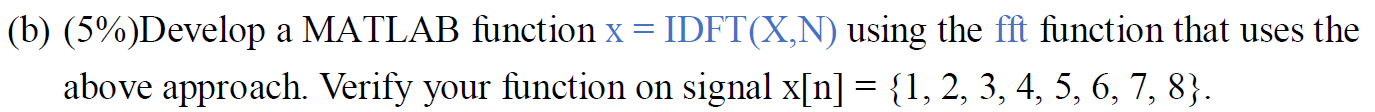

x = [1 2 3 4 5 6 7 8];
N = length(x);
X = fft(x);
X_IDFT = IDFT(X, N)

X_IDFT =      1     2     3     4     5     6     7     8


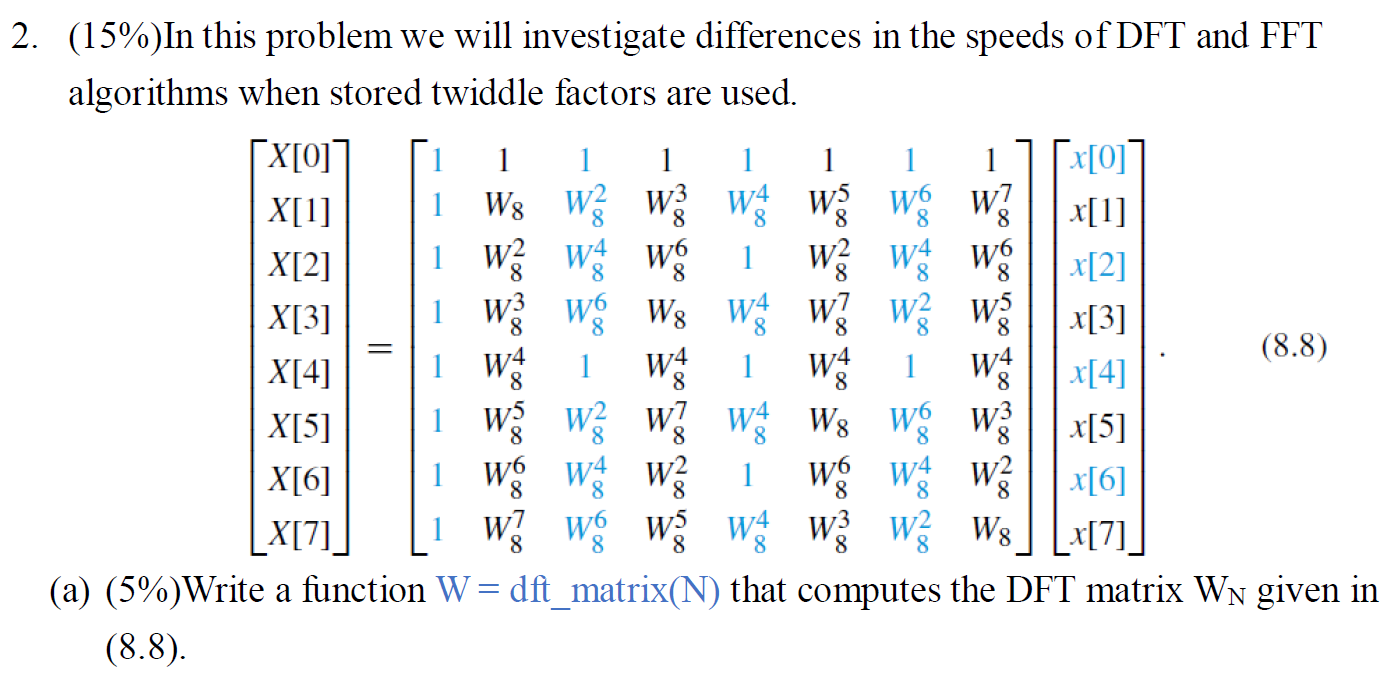

N = 8;
dft_matrix(N)

ans =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.7071 - 0.7071i   0.0000 - 1.0000i  -0.7071 - 0.7071i  -1.0000 - 0.0000i  -0.7071 + 0.7071i  -0.0000 + 1.0000i   0.7071 + 0.7071i
   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 - 0.0000i  -0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 - 0.0000i  -0.0000 + 1.0000i
   1.0000 + 0.0000i  -0.7071 - 0.7071i  -0.0000 + 1.0000i   0.7071 - 0.7071i  -1.0000 - 0.0000i   0.7071 + 0.7071i   0.0000 - 1.0000i  -0.7071 + 0.7071i
   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.7071 + 0.7071i   0.0000 - 1.0000i   0.7071 + 0.7071i  -1.0000 - 0.0000i   0.7071 - 0.7071i  -0.0000 + 1.0000i  -0.7071 - 0.7071i
   1.0000 + 0.0000i  -0.0000 + 1.0000i  -1.0000 - 0.0000i   0.0000 - 1.0000i

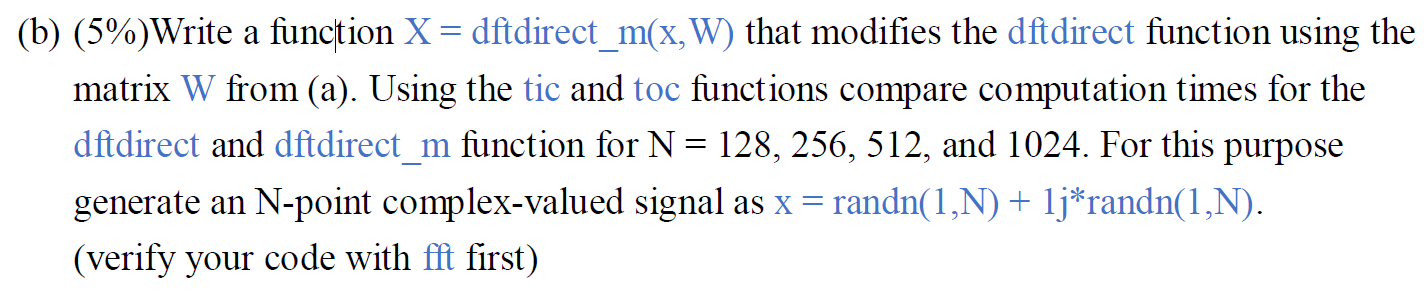

N1 = 128; N2 = 256; N3 = 512; N4 = 1024;
x1 = randn(1, N1)+1j*randn(1, N1); W1 = dft_matrix(N1);
x2 = randn(1, N2)+1j*randn(1, N2); W2 = dft_matrix(N2);
x3 = randn(1, N3)+1j*randn(1, N3); W3 = dft_matrix(N3);
x4 = randn(1, N4)+1j*randn(1, N4); W4 = dft_matrix(N4);
timer_m = zeros(1, 4);
timer_ori = zeros(1, 4);
if round(fft(x1), 5) == round(dftdirect_m(x1, W1).', 5)
    fprintf('N = %d Verified\n', N1);
end

N = 128 Verified


if round(fft(x2), 5) == round(dftdirect_m(x2, W2).', 5)
    fprintf('N = %d Verified\n', N2);
end

N = 256 Verified


if round(fft(x3), 5) == round(dftdirect_m(x3, W3).', 5)
    fprintf('N = %d Verified\n', N3);
end

N = 512 Verified


if round(fft(x4), 5) == round(dftdirect_m(x4, W4).', 5)
    fprintf('N = %d Verified\n', N4);
end

N = 1024 Verified


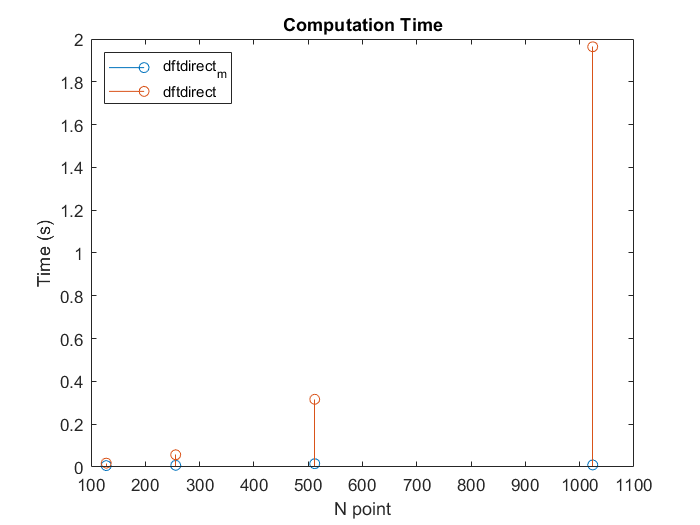

tic
X1_my = dftdirect_m(x1, W1);
timer_m(1) = toc;
tic
X1_builtin = dftdirect(x1);
timer_ori(1) = toc;
%==========================
tic
X2_my = dftdirect_m(x2, W2);
timer_m(2) = toc;
tic
X2_builtin = dftdirect(x2);
timer_ori(2) = toc;
%==========================
tic
X3_my = dftdirect_m(x3, W3);
timer_m(3) = toc;
tic
X3_builtin = dftdirect(x3);
timer_ori(3) = toc;
%==========================
tic
X4_my = dftdirect_m(x4, W4);
timer_m(4) = toc;
tic
X4_builtin = dftdirect(x4);
timer_ori(4) = toc;
%==========================
N = [128, 256, 512, 1024];
stem(N, timer_m);
hold on
stem(N, timer_ori);
hold off
legend('dftdirect_m', 'dftdirect', 'location', 'northwest');
title('Computation Time');
xlabel('N point');
ylabel('Time (s)');

dftdirect_m apparently takes much less computation time compared to dftdirect. Because DFT matrix $W_N$ is generated in advance for dftdirect_m, dftdirect_m is less time-consuming!

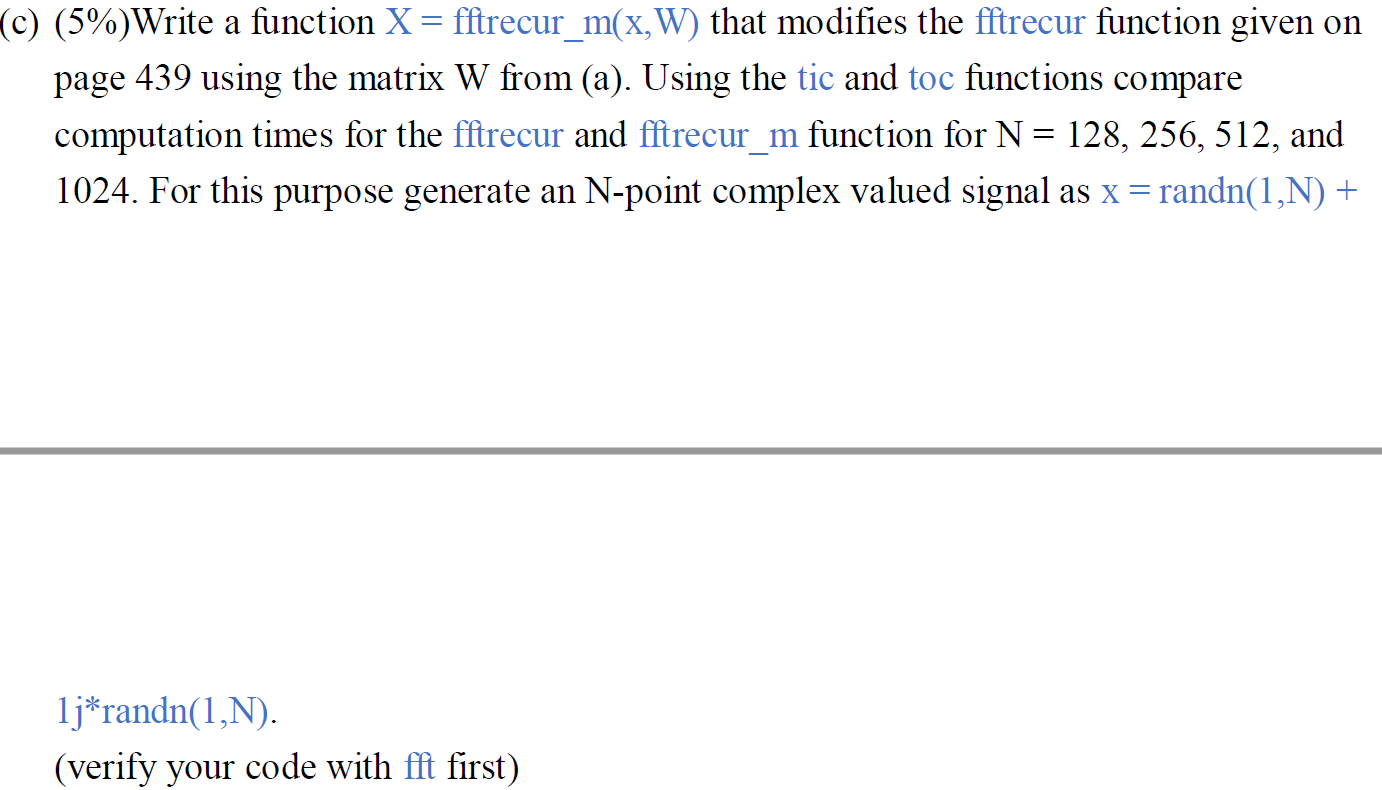\

if round(fft(x1), 5) == round(fftrecur_m(x1, dft_matrix(N1)).', 5)
    fprintf('N = %d Verified\n', N1);
end

N = 128 Verified


if round(fft(x2), 5) == round(fftrecur_m(x2, dft_matrix(N2)).', 5)
    fprintf('N = %d Verified\n', N2);
end

N = 256 Verified


if round(fft(x3), 5) == round(fftrecur_m(x3, dft_matrix(N3)).', 5)
    fprintf('N = %d Verified\n', N3);
end

N = 512 Verified


if round(fft(x4), 5) == round(fftrecur_m(x4, dft_matrix(N4)).', 5)
    fprintf('N = %d Verified\n', N1);
end

N = 128 Verified


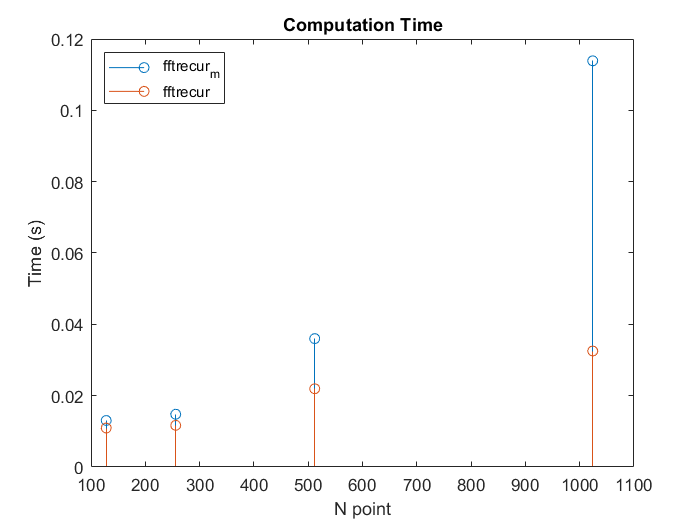

timer_m = zeros(1, 4);
timer_ori = zeros(1, 4);
tic
X1_my = fftrecur_m(x1, W1);
timer_m(1) = toc;
tic
X1_builtin = fftrecur(x1);
timer_ori(1) = toc;
%==========================
tic
X2_my = fftrecur_m(x2, W2);
timer_m(2) = toc;
tic
X2_builtin = fftrecur(x2);
timer_ori(2) = toc;
%==========================
tic
X3_my = fftrecur_m(x3, W3);
timer_m(3) = toc;
tic
X3_builtin = fftrecur(x3);
timer_ori(3) = toc;
%==========================
tic
X4_my = fftrecur_m(x4, W4);
timer_m(4) = toc;
tic
X4_builtin = fftrecur(x4);
timer_ori(4) = toc;
%==========================
N = [128, 256, 512, 1024];
stem(N, timer_m);
hold on
stem(N, timer_ori);
hold off
legend('fftrecur_m', 'fftrecur', 'location', 'northwest');
title('Computation Time');
xlabel('N point');
ylabel('Time (s)');

fftrecur_m takes much more time  than fftrecur especially N gets large. 

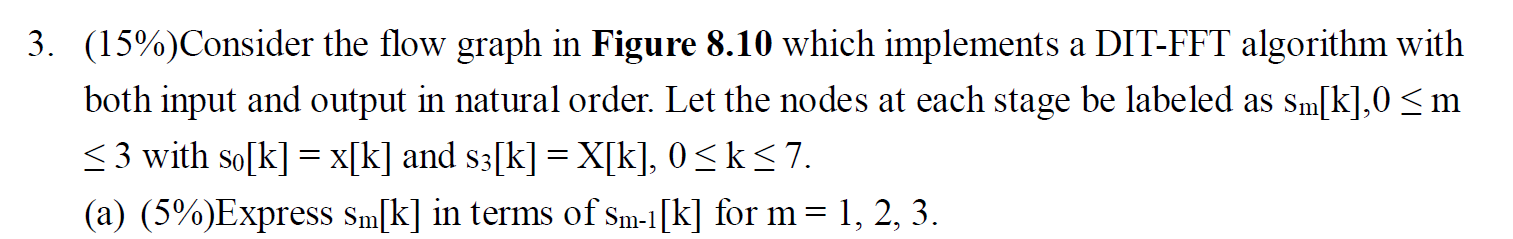

###                 
$$s_1 \left\lbrack k\right\rbrack =\left\lbrace \begin{array}{cc}
s_0 \left\lbrack k\right\rbrack +s_0 \left\lbrack k+4\right\rbrack  & 0\le k\le 3\\
s_0 \left\lbrack k-4\right\rbrack -s_0 \left\lbrack k\right\rbrack  & 4\le k\le 7
\end{array}\right.$$


###                 
$$s_2 \left\lbrack k\right\rbrack =\left\lbrace \begin{array}{cc}
s_1 \left\lbrack k\right\rbrack +s_1 \left\lbrack k+2\right\rbrack  & 0\le k\le 1\\
s_{1\left\lbrack \right.} \left\lbrack k+2\right\rbrack +{W_N^2 s}_1 \left\lbrack k+4\right\rbrack  & 2\le k\le 3\\
s_1 \left\lbrack k-4\right\rbrack -s_1 \left\lbrack k-2\right\rbrack  & 4\le k\le 5\\
s_1 \left\lbrack k-2\right\rbrack -{W_N^2 s}_1 \left\lbrack k\right\rbrack  & 6\le k\le 7
\end{array}\right.$$


###                  
$$s_3 \left\lbrack k\right\rbrack =\left\lbrace \begin{array}{cc}
s_2 \left\lbrack 2k\right\rbrack +W_N^k s_2 \left\lbrack 2k+1\right\rbrack  & 0\le k\le 3\\
s_2 \left\lbrack 2k-8\right\rbrack -W_N^{k-4} s_2 \left\lbrack 2k-7\right\rbrack  & 4\le k\le 7
\end{array}\right.$$
   

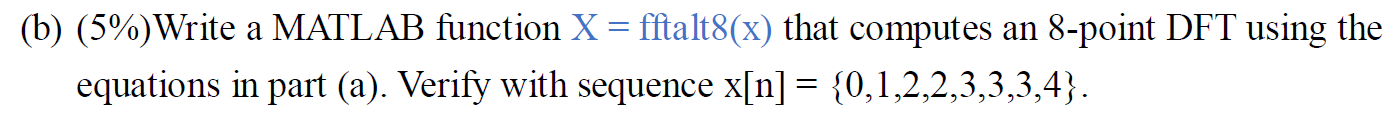

x = [0 1 2 2 3 3 3 4];
round(fft(x), 5) == round(fftalt8(x), 5)

ans = 1×8 logical array
   1   1   1   1   1   1   1   1


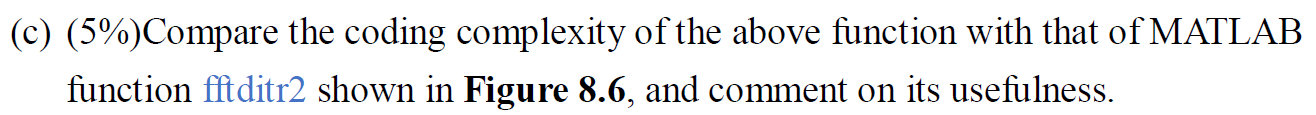

### Both of them have the time complexity of NlogN. fftdir2 is more general and convinent to use, we just need to seperate the even and odd part. However, fftalt8 has to keep in natural order so differnt stages have different computation ways.

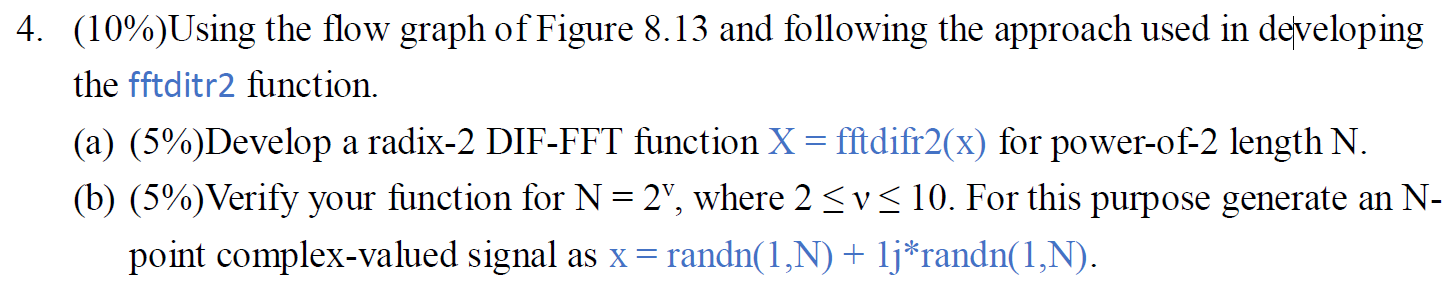

for v = 2:10
N = 2^v;
x = randn(1, N)+ 1j*randn(1, N);
    if round(fft(x), 5) == round(fftdifr2(x), 5)
        fprintf('v = %d Verified\n',v);
    end
end

v = 2 Verified
v = 3 Verified
v = 4 Verified
v = 5 Verified
v = 6 Verified
v = 7 Verified
v = 8 Verified
v = 9 Verified
v = 10 Verified


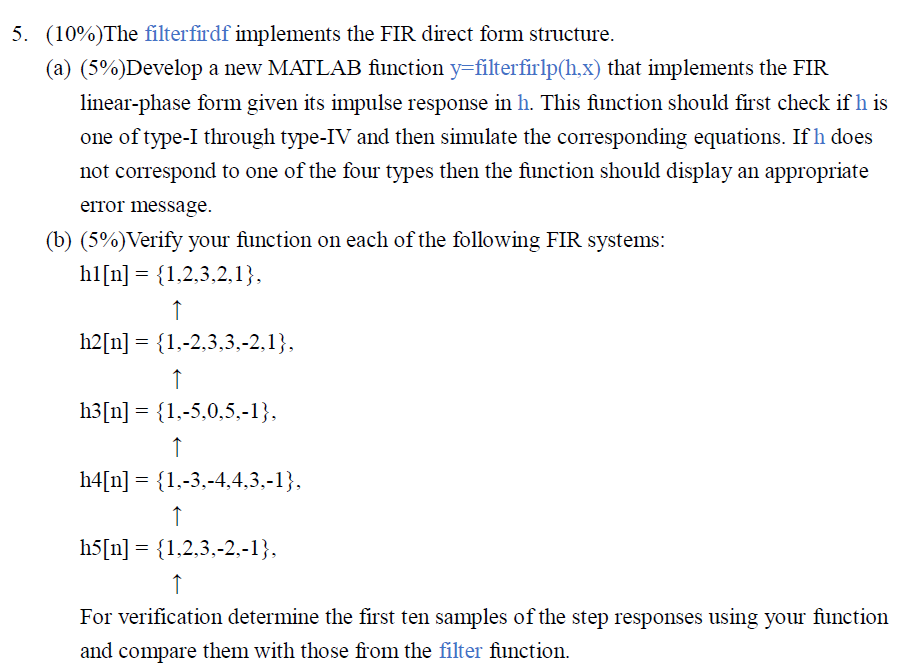

h1 = [1 2 3 2 1];
x=[1 2 3 4 5 6 7 8 9 10];
y1 = filterfirlp(h1, x);

type I

(y1(1:10)) == filter(h1, 1, x)

ans = 1×10 logical array
   1   1   1   1   1   1   1   1   1   1


h2 = [1 -2 3 3 -2 1];
y2 = filterfirlp(h2, x);

type II

(y2(1:10)) == filter(h2, 1, x)

ans = 1×10 logical array
   1   1   1   1   1   1   1   1   1   1


h3 = [1 -5 0 5 -1];
y3 = filterfirlp(h3, x);

type III

(y3(1:10)) == filter(h3, 1, x)

ans = 1×10 logical array
   1   1   1   1   1   1   1   1   1   1


h4 = [1 -3 -4 4 3 -1];
y4 = filterfirlp(h4, x);

type IV

(y4(1:10)) == filter(h4, 1, x)

ans = 1×10 logical array
   1   1   1   1   1   1   1   1   1   1


h5 = [1 2 3 4 -2 -1];
y5 = filterfirlp(h5, x);

h is not FIR linear phase filter!

(y5(1:10)) == filter(h5, 1, x)

ans = 1×10 logical array
   1   1   1   1   1   1   1   1   1   1


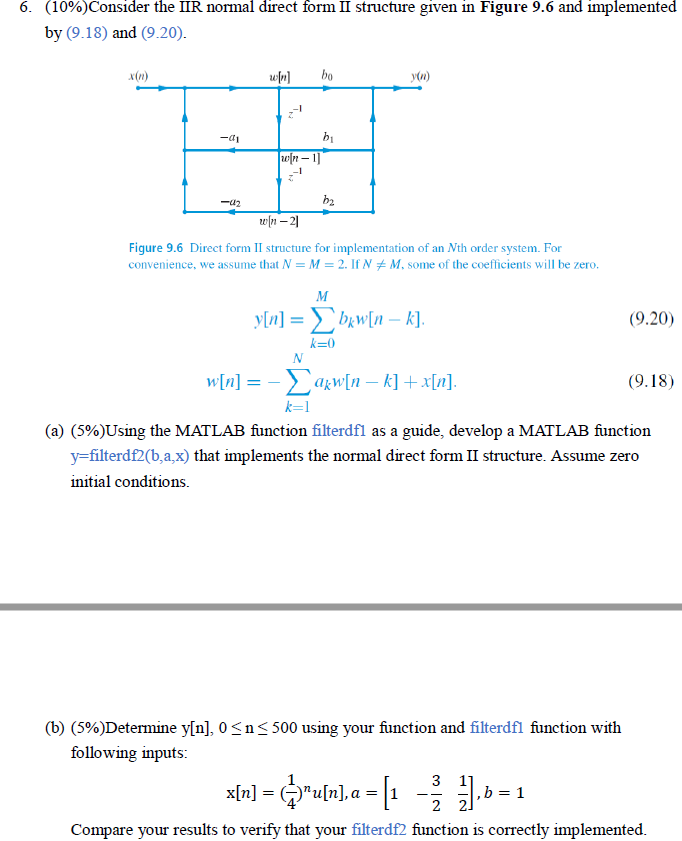

a = [1 -3/2 1/2];
b = [1];
n = 0:500;
x = (1/4).^n;
if round(filterdf2(b, a, x), 5) == round(filterdf1(b, a, x), 5)
    fprintf('Verified');
end

Verified

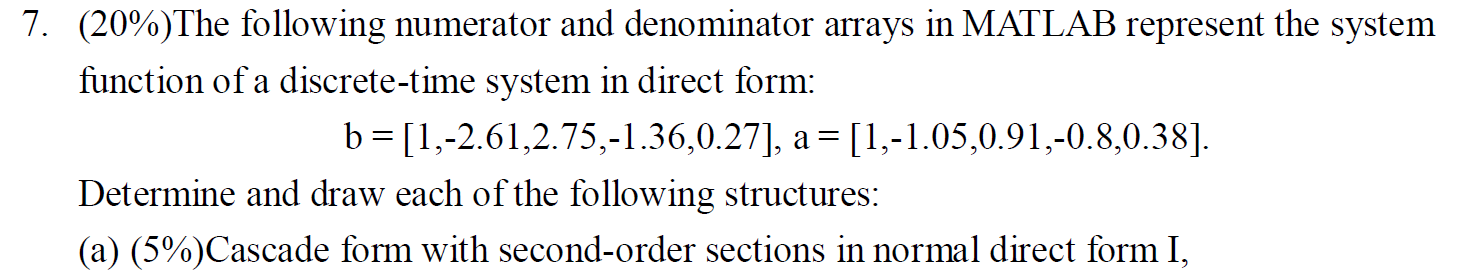

b = [1 -2.61 2.75 -1.36 0.27];
a =  [1 -1.05 0.91 -0.8 0.38];
[sos, G] = tf2sos(b, a)

sos =     1.0000   -1.4066    0.6260    1.0000   -1.3076    0.5305
    1.0000   -1.2034    0.4313    1.0000    0.2576    0.7163


G = 1

### Hence the syste, function for the cascade form is given by 

    H(z) = $\frac{1-1\ldotp 4066z^{-1} +0\ldotp 626z^{-2} }{1-1\ldotp 3076z^{-1} +0\ldotp 5305z^{-2} }\times \frac{1-1\ldotp 2034z^{-1} +0\ldotp 4313z^{-2} }{1+0\ldotp 2576z^{-1} +0\ldotp 7163z^{-2} }$

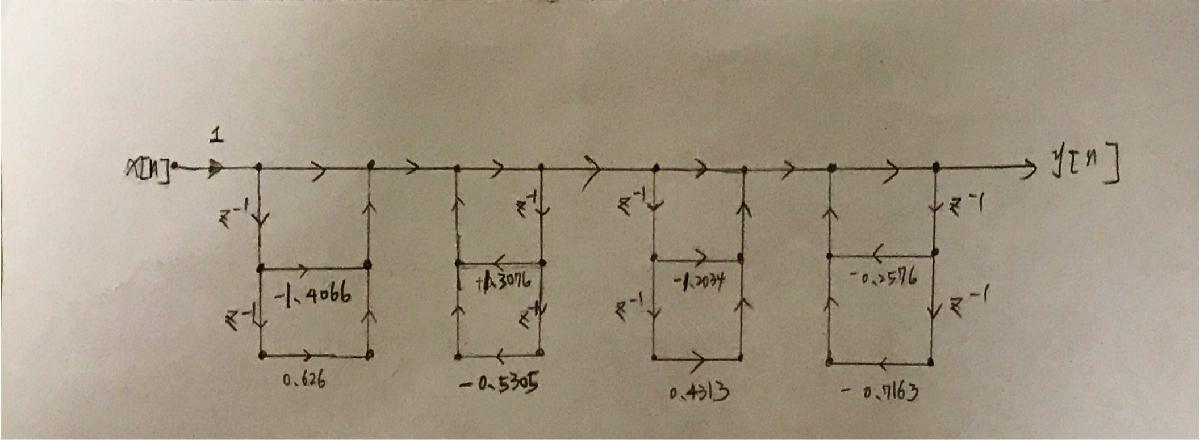

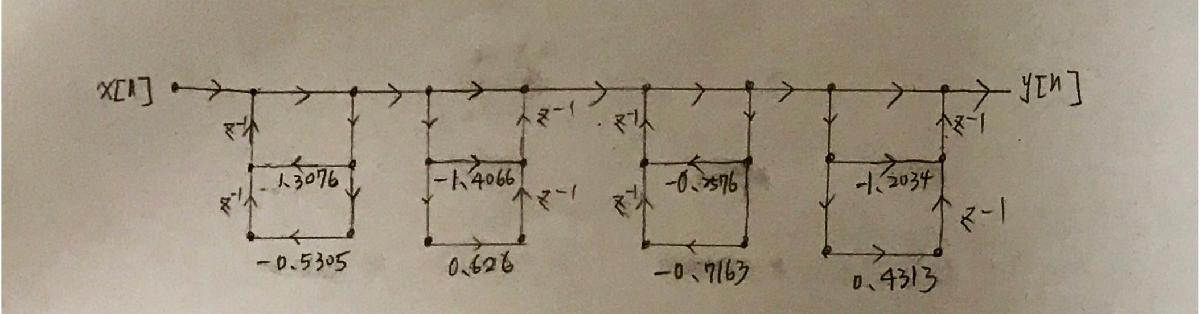

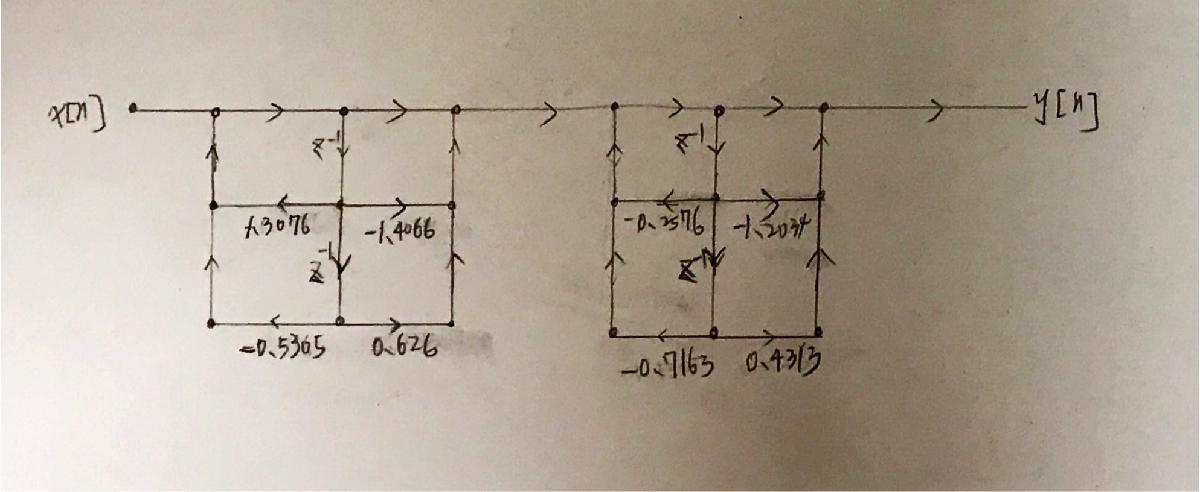

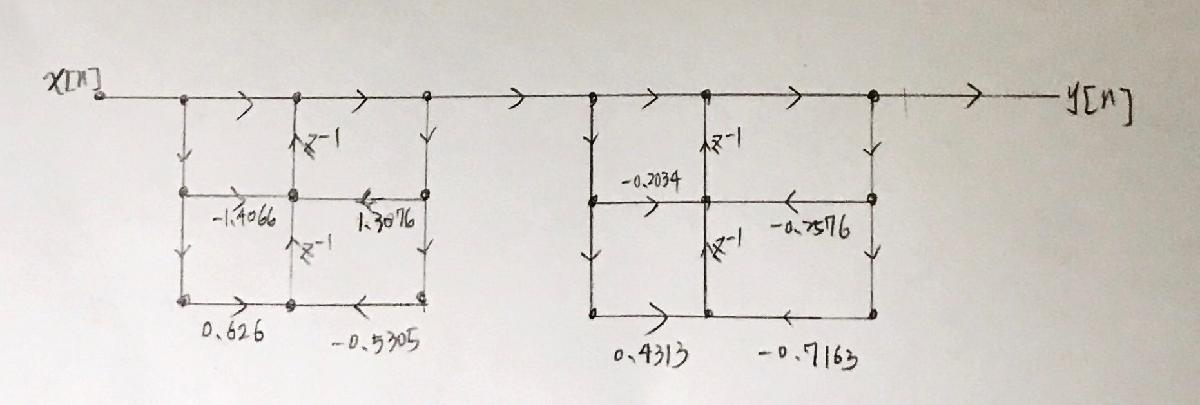

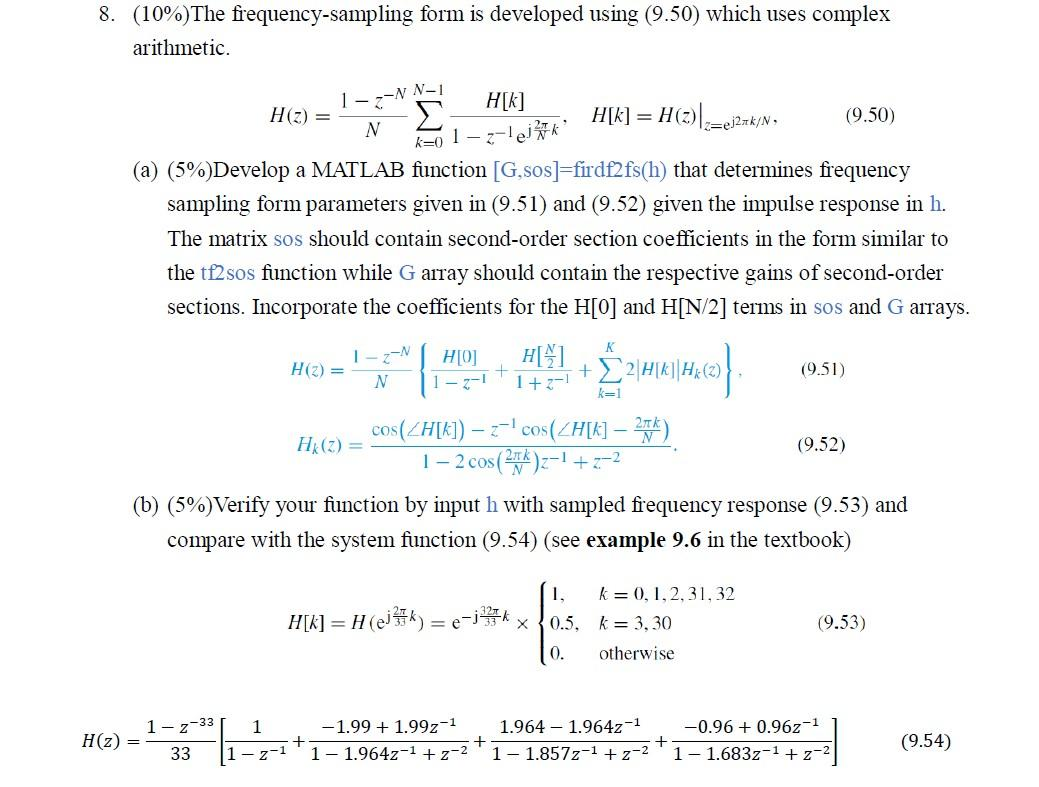

H = zeros(1, 33);
for m = 1:3
    H(m) = exp(-1j*32*pi/33*(m-1));
end
for m = 32:33
    H(m) = exp(-1j*32*pi/33*(m-1));
end
H(4) = exp(-1j*32*pi/33*3)*0.5;
H(31) = exp(-1j*32*pi/33*30)*0.5;
h = ifft(H);
[G, sos] = firdf2fs(h)

G =      1
     0
     2
     2
     1
     0
     0
     0
     0
     0


sos =     1.0000         0         0    1.0000   -1.0000         0
    1.0000         0         0    1.0000    1.0000         0
   -0.9950    0.9950         0    1.0000   -1.9640    1.0000
    0.9820   -0.9820         0    1.0000   -1.8570    1.0000
   -0.9590    0.9590         0    1.0000   -1.6830    1.0000
    0.9970   -0.6680         0    1.0000   -1.4470    1.0000
    0.1170   -0.8770         0    1.0000   -1.1600    1.0000
    0.1670    0.8280         0    1.0000   -0.8310    1.0000
   -0.9940    0.3390         0    1.0000   -0.4720    1.0000
   -0.7370    0.7100         0    1.0000   -0.0950    1.0000


After taking round on G and sos, they are consistent with the coefficient given in the 9.54.